# create downsampled vector of all aluminum times without the artifact times

run(params_path)

experiment = auditory_ephys_exp(params_path);

Choose csv file for the whisking camera
Choose csv file for the face camera


data = load_open_ephys_binary([exp_path,'/experiment1/recording1/structure.oebin'],'continuous',1,'mmap');
%aud_data = data.Data.Data.mapped(32 + mic,:)

% find time samples in video based on whiskers for both whiskers and face
whiskingStart = experiment.Cams.whsiking.csv_start_frame

whiskingStart = 402

expLength = length(data.Data.Data.mapped)

expLength = 67777280

whiskingEnd = find(experiment.Cams.whsiking.csv_aligned_frames < expLength);
whiskingEnd = whiskingEnd(end)

whiskingEnd = 902439

whiskingVector = [whiskingStart:whiskingEnd]

whiskingVector =    402   403   404   405   406   407   408   409   410   411   412   413   414   415   416   417   418   419   420   421   422   423   424   425   426   427   428   429   430   431   432   433   434   435   436   437   438   439   440   441   442   443   444   445   446   447   448   449   450   451


sampleVector = experiment.Cams.whsiking.csv_aligned_frames(whiskingVector)

sampleVector =        74828
       74966
       75038
       75115
       75211
       75266
       75342
       75414
       75486
       75561



[~,faceStart] = min(abs(experiment.Cams.face.csv_aligned_frames - sampleVector(1)))

faceStart = 101

faceVector = [faceStart:faceStart+length(whiskingVector)-1]

faceVector =    101   102   103   104   105   106   107   108   109   110   111   112   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150


% Extract aluminum times
artifactStart = experiment.Conditions.artifact_times(2) * 30

artifactStart = 75000

artifactEnd = experiment.Conditions.artifact_times(1) * 30

artifactEnd = 90000

all_times = [experiment.Conditions.all_changes + artifactStart,[experiment.Conditions.all_changes(2:end);sampleVector(end)]-artifactEnd]

all_times = 34×2 int64 matrix
    4780464    6505018
    6670018    8394572
    8559572   10272128
   10437128   12149685
   12314685   14033243
   14198243   15910800
   16075800   17800355
   17965355   19677955
   19842955   21567509
   21732509   23457064


aluminumTimes = all_times(experiment.Conditions.condition_classification == 1,:)

aluminumTimes = 15×2 int64 matrix
   10437128   12149685
   12314685   14033243
   16075800   17800355
   19842955   21567509
   25499620   27218179
   31150290   32874844
   34917444   36630001
   36795001   38513559
   48102340   49814940
   49979940   51704494


% create idx vector for aluminum
aluminumInd = []


aluminumInd =

     []



for al = 1:length(aluminumTimes)
    tempInd = find(sampleVector > aluminumTimes(al,1) & sampleVector < aluminumTimes(al,2))
    aluminumInd = [aluminumInd;tempInd]
end

tempInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       163067
      163068
      163069
      163070
      163071
      163072
      163073
      163074
      163075
      163076


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       213183
      213184
      213185
      213186
      213187
      213188
      213189
      213190
      213191
      213192


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       263372
      263373
      263374
      263375
      263376
      263377
      263378
      263379
      263380
      263381


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       338741
      338742
      338743
      338744
      338745
      338746
      338747
      338748
      338749
      338750


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       414032
      414033
      414034
      414035
      414036
      414037
      414038
      414039
      414040
      414041


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       464225
      464226
      464227
      464228
      464229
      464230
      464231
      464232
      464233
      464234


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       489242
      489243
      489244
      489245
      489246
      489247
      489248
      489249
      489250
      489251


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       639902
      639903
      639904
      639905
      639906
      639907
      639908
      639909
      639910
      639911


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       664919
      664920
      664921
      664922
      664923
      664924
      664925
      664926
      664927
      664928


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       740210
      740211
      740212
      740213
      740214
      740215
      740216
      740217
      740218
      740219


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       765225
      765226
      765227
      765228
      765229
      765230
      765231
      765232
      765233
      765234


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       790238
      790239
      790240
      790241
      790242
      790243
      790244
      790245
      790246
      790247


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       815254
      815255
      815256
      815257
      815258
      815259
      815260
      815261
      815262
      815263


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


tempInd =       890535
      890536
      890537
      890538
      890539
      890540
      890541
      890542
      890543
      890544


aluminumInd =       138053
      138054
      138055
      138056
      138057
      138058
      138059
      138060
      138061
      138062


% create samplevector for aluminum
aluminumVector = sampleVector(aluminumInd)

aluminumVector =     10437131
    10437194
    10437277
    10437350
    10437430
    10437497
    10437581
    10437650
    10437729
    10437797


% create video frame whisker vector
aluminumWhiskerVector = whiskingVector(aluminumInd)'

aluminumWhiskerVector =       138454
      138455
      138456
      138457
      138458
      138459
      138460
      138461
      138462
      138463


% create video frame face vector
aluminumFaceVector = faceVector(aluminumInd)'

aluminumFaceVector =       138153
      138154
      138155
      138156
      138157
      138158
      138159
      138160
      138161
      138162


## **create matrix for prediction with linear regression**

### **The model is a matrix with the following rows as variables and columuns as observations:**

- ** Encoder**

- **whiskingMotion_1**

- **whisking motSVD_0 (10 first)**

- **whisking motSVD_1 (10 first)**

- **faceMotion_1**

- **face motSVD_1 (10 first)**

- **Running from face camera**

**Predictions should be done on a matrix ordered the same why**

**The output will be a vector of the sound from open ephys sampled by the sampleVector and threshold **

% get the sound vector 
aud_data = data.Data.Data.mapped(34,:)

aud_data = 1×67777280 int16 row vector
   425   440   443   477   413   473   456   470   465   443   407   395   466   451   431   426   435   434   427   425   473   419   407   456   411   429   465   435   483   458   489   459   415   413   474   435   443   422   397   487   424   431   431   471   487   467   498   478   451   455


mkdir analysis
cd analysis
audiowrite("aud_data.wav",aud_data,30000)

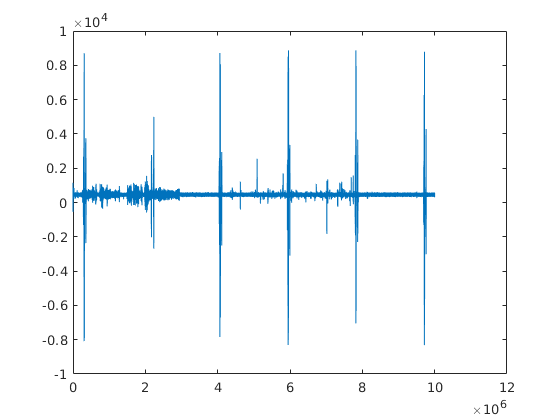

% clean artifacts clipping
figure; plot(aud_data(10000000:20000000))

for art = 1:length(all_times)
    chg_time = experiment.Conditions.all_changes(art);
    aud_data(chg_time-artifactEnd:chg_time+artifactStart) = median(aud_data);
end

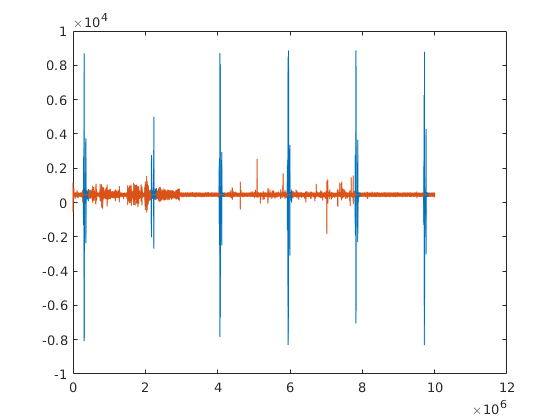

hold on; plot(aud_data(10000000:20000000))

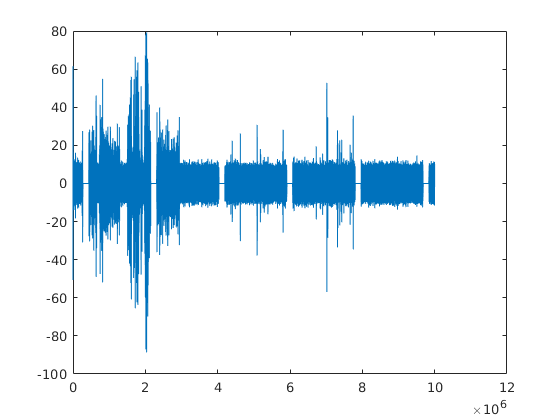

%filter data and keep just the aluminum sound componenets
[b,a] = cheby1(5,20,[10000]/15000,'high');
aud_data_filt = filtfilt(b,a,double(aud_data));
figure; plot(aud_data_filt(10000000:20000000))

% envelope aud_data
aud_data_env = envelope(aud_data_filt,300,"analytic");

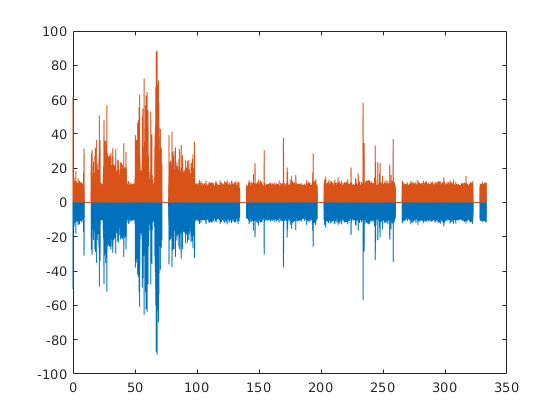

figure; plot([1:10000001]/30000,aud_data_filt(10000000:20000000))
hold on; plot([1:10000001]/30000,aud_data_env(10000000:20000000))

% filter envelope to gte only slow changes
[bn,an] = butter(3,[80]/15000,"low");
aud_data_env = filtfilt(bn,an,double(aud_data_env));

aud_data_cleaned = normalize(aud_data_env,'range',[0,1])

aud_data_cleaned =     0.0453    0.0454    0.0456    0.0457    0.0458    0.0459    0.0461    0.0462    0.0463    0.0465    0.0466    0.0467    0.0469    0.0470    0.0471    0.0473    0.0474    0.0475    0.0477    0.0478    0.0479    0.0481    0.0482    0.0483    0.0485    0.0486    0.0488    0.0489    0.0490    0.0492    0.0493    0.0494    0.0496    0.0497    0.0498    0.0500    0.0501    0.0503    0.0504    0.0505    0.0507    0.0508    0.0509    0.0511    0.0512    0.0513    0.0515    0.0516    0.0518    0.0519


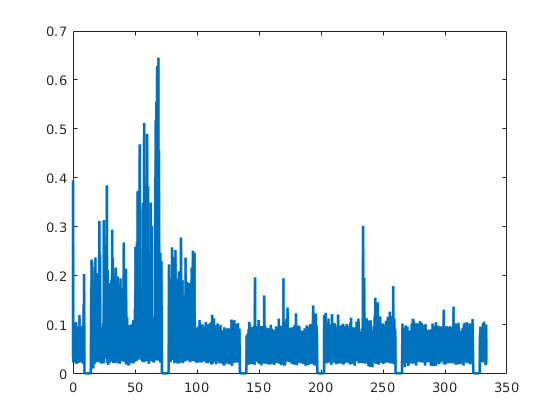

figure;plot([1:10000001]/30000,aud_data_cleaned(10000000:20000000),'LineWidth',2)

% clean data below threshold
%aud_data_cleaned(aud_data_cleaned<0.11) = median(aud_data_cleaned);


figure; plot([1:10000001]/30000,aud_data_cleaned(10000000:20000000),'LineWidth',2)



experiment.sound_events.fullSound = aud_data;
experiment.sound_events.fullSoundCleaned = aud_data_cleaned;

aud_data_Alum = aud_data_cleaned(aluminumVector)

aud_data_Alum =     0.0633    0.0773    0.0912    0.0987    0.0959    0.0842    0.0711    0.0686    0.0687    0.0646    0.0544    0.0422    0.0300    0.0273    0.0372    0.0540    0.0621    0.0566    0.0530    0.0630    0.0755    0.0767    0.0718    0.0683    0.0639    0.0584    0.0538    0.0545    0.0611    0.0785    0.1003    0.1140    0.1130    0.1102    0.1145    0.1203    0.1150    0.0981    0.0811    0.0680    0.0583    0.0553    0.0585    0.0697    0.0900    0.1217    0.1511    0.1725    0.1696    0.1508


%aud_data_cleaned(aud_data_cleaned < 0.1) = 0

figure; plot(aud_data_Alum)

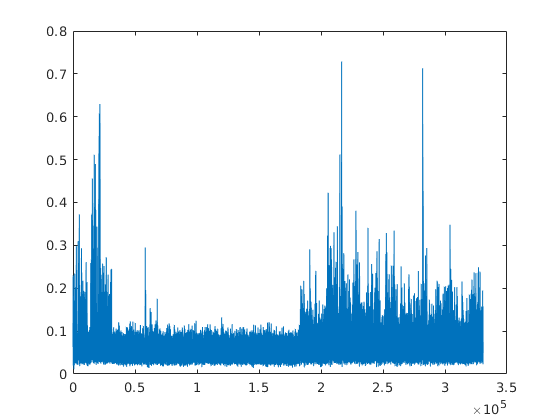

% get encoder data and high pass filter 

encoder_data = data.Data.Data.mapped(32 + encoder,:)
[b,a] = butter(3,[2 400]/15000,'bandpass')
encoder_data = filtfilt(b,a,double(encoder_data))

figure; plot(encoder_data)

encoder_data = 1×67777280 int16 row vector
   20533   20542   20543   20547   20519   20539   20531   20537   20535   20547   20545   20547   20547   20535   20539   20534   20555   20538   20551   20527   20545   20547   20545   20542   20537   20529   20527   20537   20539   20537   20539   20539   20531   20523   20547   20536   20533   20537   20528   20546   20539   20544   20538   20544   20541   20543   20543   20546   20547   20543


encoder_data = envelope(normalize(encoder_data))

b = 	1.0e+-3 *

    0.0667         0   -0.2002         0    0.2002         0   -0.0667


a =     1.0000   -5.8332   14.1799  -18.3866   13.4130   -5.2194    0.8464


% import the whisking moiton vectors

encoder_data = 	1.0e+04 *

    0.0004    0.0005    0.0005    0.0006    0.0006    0.0007    0.0007    0.0007    0.0008    0.0008    0.0009    0.0009    0.0009    0.0010    0.0010    0.0010    0.0010    0.0011    0.0011    0.0011    0.0011    0.0011    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0012    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013    0.0013


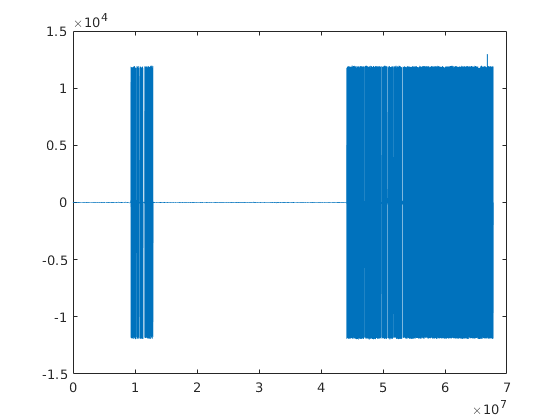

[file,path] = uigetfile();
cd(path)

load(file,'motSVD_1','motion_1')

% add encoder to the modal and prediction matrices

encoder_data =     0.0254    0.0237    0.0238    0.0232    0.0233    0.0229    0.0229    0.0226    0.0225    0.0223    0.0222    0.0220    0.0219    0.0216    0.0215    0.0213    0.0212    0.0210    0.0209    0.0207    0.0206    0.0204    0.0202    0.0201    0.0199    0.0198    0.0196    0.0195    0.0194    0.0192    0.0191    0.0190    0.0189    0.0187    0.0187    0.0185    0.0184    0.0183    0.0182    0.0181    0.0181    0.0180    0.0179    0.0178    0.0177    0.0176    0.0176    0.0175    0.0174    0.0173


modelMatrix = encoder_data(aluminumVector)'
predictionMatrix = encoder_data(sampleVector)'


motSVD_1(:,1:250) = envelope(normalize(motSVD_1(:,1:250)))
motion_1 = envelope(normalize(motion_1))

modelMatrix(:,2) = motion_1(aluminumWhiskerVector)

modelMatrix =     0.0927
    0.0953
    0.0964
    0.0960
    0.0951
    0.0977
    0.0993
    0.0993
    0.0961
    0.0959


predictionMatrix(:,2) = motion_1(whiskingVector)

predictionMatrix =     0.0008
    0.0014
    0.0024
    0.0006
    0.0015
    0.0009
    0.0014
    0.0015
    0.0011
    0.0002


modelMatrix(:,3:252) = motSVD_1(aluminumWhiskerVector,1:250)
predictionMatrix(:,3:252) = motSVD_1(whiskingVector,1:250)


motSVD_1 = 902555×500 single matrix
    5.5053    0.3880    0.7078    2.2234    0.2819    0.3620    1.6326    0.3821    0.5349    2.3053    0.5461    2.5771    2.1532    0.5338    0.3923    1.5512    2.5297    3.3358    1.0660    1.4733    0.5061    1.0277    1.3789    0.3449    0.5067    1.9344    0.6001    0.7979    2.0669    1.1031    0.3490    0.3344    1.0476    1.2310    0.3525    0.0986    0.1589    2.5205    1.8206    1.7279    1.1112    0.9556    1.7677    0.0741    0.3414    0.9799    1.2064    0.1514    1.6115    1.2045
    4.6517    0.2738    0.6385    1.7768    0.6524    0.3263    0.3478    0.6388    0.9410    1.2291    0.4477    1.9683    1.7498    0.8472    0.2703    0.9987    2.2117    1.9186    1.5294    1.2699    0.5117    0.2115    0.8335    1.1063    0.1242    1.3089    0.7528    0.4492    1.6697    1.1580    0.2209    0.3538    0.3312    0.7333    0.8035    0.2229    0.0184    2.2418    1.7387    1.1178    0.7385    1.4202    1.2614    0.2459    0.0771    0.6935   

% save the model and prediction vectors 

motion_1 = 1×902555 single row vector
    5.0273    4.2121    4.2991    3.9315    4.0736    3.8174    3.8845    3.7678    3.8847    3.7764    3.7580    3.6444    3.5614    3.5259    3.8264    3.5384    3.7130    3.4732    3.6065    3.4343    3.5708    3.4407    3.5345    3.4225    3.5150    3.4218    3.4735    3.3812    3.4305    3.3437    3.3918    3.3045    3.3399    3.2562    3.3570    3.2493    3.3051    3.2486    3.2709    3.1976    3.2555    3.1541    3.1969    3.1573    3.1631    3.1715    3.1897    3.1068    3.1382    3.0948


cd analysis/
save('model_matrices.mat','modelMatrix',"aud_data_Alum",'predictionMatrix','sampleVector','aluminumWhiskerVector')

modelMatrix =     0.0927    1.5740
    0.0953    1.7830
    0.0964    1.4228
    0.0960    1.6244
    0.0951    1.1777
    0.0977    1.4579
    0.0993    1.6352
    0.0993    1.6843
    0.0961    1.4984
    0.0959    1.4536


save('FVB109_904.mat',"experiment")

predictionMatrix =     0.0008    2.2034
    0.0014    2.7228
    0.0024    1.2730
    0.0006    3.0757
    0.0015    4.0624
    0.0009    2.8255
    0.0014    3.1943
    0.0015    2.8768
    0.0011    3.0061
    0.0002    2.7478


clearvars -except modelMatrix aud_data_Alum predictionMatrix sampleVector aluminumWhiskerVector

modelMatrix =     0.0927    1.5740    1.0425    3.3779    3.1878    2.1557    1.4355    0.5611    0.3271    0.6660    3.0245    0.4329    5.3558    1.1995    1.1561    1.4069    1.4890    4.8152    1.6716    1.8437    1.6748    1.6047    1.6522    2.0852    2.3215    0.8435    2.2268    3.3061    1.2682    0.2259    1.3780    0.5145    0.3289    0.5063    1.7741    1.1435    1.0723    2.9349    1.7062    3.0522    3.1504    1.5373    2.7681    2.2067    1.7225    1.2142    1.7680    1.0888    3.0203    0.8091
    0.0953    1.7830    1.1187    3.2174    3.2207    2.1076    2.6097    0.5876    0.7210    0.2804    2.7227    1.0758    5.9944    2.0163    0.6360    1.2630    1.6510    4.8715    1.3441    2.3085    1.0207    0.7417    1.8184    3.2141    2.1373    1.3130    2.3040    2.8075    1.6733    0.6779    1.7924    0.7695    1.7986    1.6882    2.6001    0.8157    1.8044    3.4423    1.3963    2.8018    2.6289    2.6132    2.5788    0.6442    1.1952    1.9113    2.4283    2.4994    1

figure; plot(aud_data_Alum)

predictionMatrix =     0.0008    2.2034    2.9112    0.1339    0.1782    0.7768    0.5129    0.2385    0.1652    0.0713    0.1748    0.8344    0.2474    0.5344    0.3897    0.2805    0.3110    0.6105    1.0184    0.2114    0.5892    0.4964    0.1324    0.2716    0.6294    0.6744    0.1108    0.6168    0.2941    0.0637    0.6591    0.5745    0.0685    0.5197    0.3771    0.6375    0.1632    0.4912    0.3562    0.9934    0.4769    0.5322    0.3744    0.6946    0.4777    0.5566    0.0642    0.1246    0.2907    0.3033
    0.0014    2.7228    2.6478    0.7093    0.2753    0.3176    0.3520    0.2723    0.2582    0.3317    0.6936    0.1633    0.3106    0.1489    0.5082    0.3661    0.7193    0.5643    1.1870    0.5044    0.6902    0.4148    0.5340    0.2801    0.4453    1.4242    0.1247    0.6287    0.1602    0.6098    0.1685    0.3017    0.0653    0.2985    0.2040    0.7544    0.3943    0.5089    0.1133    0.9899    0.7921    0.7467    0.9341    1.0958    0.4584    0.7880    0.8965    0.0707

hold on; plot(modelMatrix(:,1)/50)

modelMatrix(:,253) = aud_data_Alum

%Annotate quiet periods and movement periods
movement_times = [1,2900;3940,11640;14140,31160;182540,330703]
quiet_times = [2901,3939;11641,14139;31161,182539]

% split modelMatrix to quiet and movement periods and reduce the below
% threshold movement

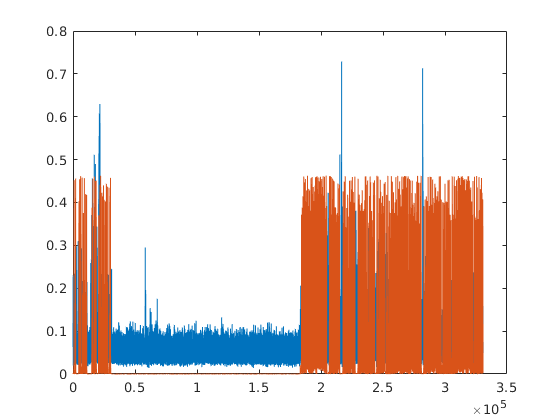

modelClean = [];
model_quiet =[];

for tt = 1:4
    model_temp = modelMatrix(movement_times(tt,1):movement_times(tt,2),:);

modelMatrix =     0.0927    1.5740    1.0425    3.3779    3.1878    2.1557    1.4355    0.5611    0.3271    0.6660    3.0245    0.4329    5.3558    1.1995    1.1561    1.4069    1.4890    4.8152    1.6716    1.8437    1.6748    1.6047    1.6522    2.0852    2.3215    0.8435    2.2268    3.3061    1.2682    0.2259    1.3780    0.5145    0.3289    0.5063    1.7741    1.1435    1.0723    2.9349    1.7062    3.0522    3.1504    1.5373    2.7681    2.2067    1.7225    1.2142    1.7680    1.0888    3.0203    0.8091
    0.0953    1.7830    1.1187    3.2174    3.2207    2.1076    2.6097    0.5876    0.7210    0.2804    2.7227    1.0758    5.9944    2.0163    0.6360    1.2630    1.6510    4.8715    1.3441    2.3085    1.0207    0.7417    1.8184    3.2141    2.1373    1.3130    2.3040    2.8075    1.6733    0.6779    1.7924    0.7695    1.7986    1.6882    2.6001    0.8157    1.8044    3.4423    1.3963    2.8018    2.6289    2.6132    2.5788    0.6442    1.1952    1.9113    2.4283    2.4994    1

    aud_below = model_temp(:,253) < 0.11;
%     sum(aud_below)
%     model_temp = model_temp(aud_below,:);

movement_times =            1        2900
        3940       11640
       14140       31160
      182540      330703


    modelClean = [modelClean;model_temp];

quiet_times =         2901        3939
       11641       14139
       31161      182539


    if tt<4
        modelTemp = modelMatrix(quiet_times(tt,1):quiet_times(tt,2),:);
        mm = cvpartition(length(modelTemp),"HoldOut",0.3);
        idxquiet = test(mm);
        sum(idxquiet)
        modelTemp = modelTemp(idxquiet,:);
        aud_below = modelTemp(:,253) < 0.13;
        modelTemp(aud_below,253) = 0;
        modelClean = [modelClean;modelTemp];
    end
end

ans = 311

ans = 749

ans = 45413

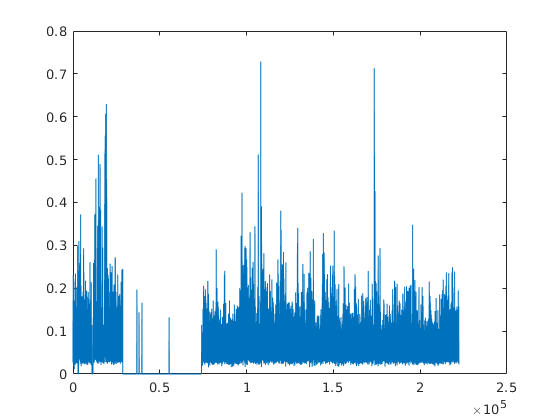

figure; 
plot(modelClean(:,253))

%modelClean(:,1:252) = envelope(normalize(modelClean(:,1:252)))


figure;
plot(modelClean(:,1))

%predictionMatrix = envelope(normalize(predictionMatrix))

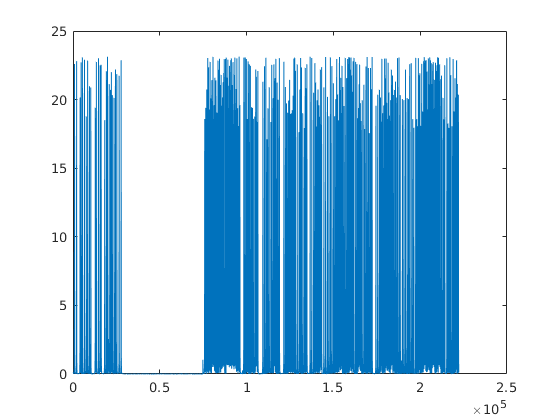

figure;

plot(predictionMatrix(:,100))

save("modelclean.mat","modelClean","predictionMatrix","sampleVector")

clearvars -except   modelClean predictionMatrix sampleVector

data_length = length(modelClean(:,1))
data_length/400

data10 = round(0.1*data_length)
data10/400
lengthTestSection = round(data10/5)

testStarts = randperm(data_length,5)

data_length = 222259

testEnds = testStarts+lengthTestSection

ans = 555.6475

idxTest =[];
for tt = 1:5

data10 = 22226

    testTemp = testStarts(tt):testEnds(tt)

ans = 55.5650

    idxTest = [idxTest,testTemp]

lengthTestSection = 4445

end

idxTest = ismember(1:data_length,idxTest)

testStarts =       144650       25097      182887      104350       99854


idxTrain = ~idxTest

testEnds =       149095       29542      187332      108795      104299


    % split data to train test
modelTrain = modelClean(~idxTest,:)
modelTest = modelClean(idxTest,:)

%aud_data_Train = aud_data_Alum(idxTrain)

testTemp =       144650      144651      144652      144653      144654      144655      144656      144657      144658      144659      144660      144661      144662      144663      144664      144665      144666      144667      144668      144669      144670      144671      144672      144673      144674      144675      144676      144677      144678      144679      144680      144681      144682      144683      144684      144685      144686      144687      144688      144689      144690      144691      144692      144693      144694      144695      144696      144697      144698      144699


idxTest =       144650      144651      144652      144653      144654      144655      144656      144657      144658      144659      144660      144661      144662      144663      144664      144665      144666      144667      144668      144669      144670      144671      144672      144673      144674      144675      144676      144677      144678      144679      144680      144681      144682      144683      144684      144685      144686      144687      144688      144689      144690      144691      144692      144693      144694      144695      144696      144697      144698      144699


testTemp =        25097       25098       25099       25100       25101       25102       25103       25104       25105       25106       25107       25108       25109       25110       25111       25112       25113       25114       25115       25116       25117       25118       25119       25120       25121       25122       25123       25124       25125       25126       25127       25128       25129       25130       25131       25132       25133       25134       25135       25136       25137       25138       25139       25140       25141       25142       25143       25144       25145       25146


idxTest =       144650      144651      144652      144653      144654      144655      144656      144657      144658      144659      144660      144661      144662      144663      144664      144665      144666      144667      144668      144669      144670      144671      144672      144673      144674      144675      144676      144677      144678      144679      144680      144681      144682      144683      144684      144685      144686      144687      144688      144689      144690      144691      144692      144693      144694      144695      144696      144697      144698      144699


testTemp =       182887      182888      182889      182890      182891      182892      182893      182894      182895      182896      182897      182898      182899      182900      182901      182902      182903      182904      182905      182906      182907      182908      182909      182910      182911      182912      182913      182914      182915      182916      182917      182918      182919      182920      182921      182922      182923      182924      182925      182926      182927      182928      182929      182930      182931      182932      182933      182934      182935      182936


idxTest =       144650      144651      144652      144653      144654      144655      144656      144657      144658      144659      144660      144661      144662      144663      144664      144665      144666      144667      144668      144669      144670      144671      144672      144673      144674      144675      144676      144677      144678      144679      144680      144681      144682      144683      144684      144685      144686      144687      144688      144689      144690      144691      144692      144693      144694      144695      144696      144697      144698      144699


testTemp =       104350      104351      104352      104353      104354      104355      104356      104357      104358      104359      104360      104361      104362      104363      104364      104365      104366      104367      104368      104369      104370      104371      104372      104373      104374      104375      104376      104377      104378      104379      104380      104381      104382      104383      104384      104385      104386      104387      104388      104389      104390      104391      104392      104393      104394      104395      104396      104397      104398      104399


idxTest =       144650      144651      144652      144653      144654      144655      144656      144657      144658      144659      144660      144661      144662      144663      144664      144665      144666      144667      144668      144669      144670      144671      144672      144673      144674      144675      144676      144677      144678      144679      144680      144681      144682      144683      144684      144685      144686      144687      144688      144689      144690      144691      144692      144693      144694      144695      144696      144697      144698      144699


testTemp =        99854       99855       99856       99857       99858       99859       99860       99861       99862       99863       99864       99865       99866       99867       99868       99869       99870       99871       99872       99873       99874       99875       99876       99877       99878       99879       99880       99881       99882       99883       99884       99885       99886       99887       99888       99889       99890       99891       99892       99893       99894       99895       99896       99897       99898       99899       99900       99901       99902       99903


idxTest =       144650      144651      144652      144653      144654      144655      144656      144657      144658      144659      144660      144661      144662      144663      144664      144665      144666      144667      144668      144669      144670      144671      144672      144673      144674      144675      144676      144677      144678      144679      144680      144681      144682      144683      144684      144685      144686      144687      144688      144689      144690      144691      144692      144693      144694      144695      144696      144697      144698      144699


%aud_data_test = aud_data_Alum(idxTest)

figure;

idxTest = 1×222259 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


plot(modelTest(:,253))

idxTrain = 1×222259 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1


figure;

modelTrain =     0.0927    1.5740    1.0425    3.3779    3.1878    2.1557    1.4355    0.5611    0.3271    0.6660    3.0245    0.4329    5.3558    1.1995    1.1561    1.4069    1.4890    4.8152    1.6716    1.8437    1.6748    1.6047    1.6522    2.0852    2.3215    0.8435    2.2268    3.3061    1.2682    0.2259    1.3780    0.5145    0.3289    0.5063    1.7741    1.1435    1.0723    2.9349    1.7062    3.0522    3.1504    1.5373    2.7681    2.2067    1.7225    1.2142    1.7680    1.0888    3.0203    0.8091
    0.0953    1.7830    1.1187    3.2174    3.2207    2.1076    2.6097    0.5876    0.7210    0.2804    2.7227    1.0758    5.9944    2.0163    0.6360    1.2630    1.6510    4.8715    1.3441    2.3085    1.0207    0.7417    1.8184    3.2141    2.1373    1.3130    2.3040    2.8075    1.6733    0.6779    1.7924    0.7695    1.7986    1.6882    2.6001    0.8157    1.8044    3.4423    1.3963    2.8018    2.6289    2.6132    2.5788    0.6442    1.1952    1.9113    2.4283    2.4994    1.

plot(modelTrain(:,253))

modelTest =     0.5457    1.2053    1.4833    0.4977    0.4356    0.8939    0.6374    0.8586    1.2030    1.2674    1.8987    0.4609    0.2150    1.7919    0.4481    1.5712    0.0998    0.6742    0.7183    0.5560    1.3137    0.2796    1.1862    0.8244    1.8873    1.9825    1.9426    0.9160    2.3164    0.6473    2.1903    1.6106    2.3114    1.2155    0.7068    1.8032    0.6471    0.8851    1.1475    0.9497    1.3419    0.4526    0.5267    1.2506    1.1612    1.2723    1.3546    1.3497    0.5857    1.1544
    0.5546    1.2003    1.4124    0.1682    0.1801    0.6254    1.5713    0.1939    1.8068    1.1279    2.0607    1.2691    0.7264    1.6210    0.7548    2.2823    0.8756    1.5022    0.3263    0.5476    0.9009    0.4369    1.2239    0.8066    0.9210    1.9029    1.0403    1.0792    1.3956    0.3133    1.1627    0.8840    1.5189    1.5529    1.4861    1.5392    1.4494    1.6093    1.0525    0.4576    1.6340    0.5565    1.1079    1.1706    2.0367    1.4049    0.7762    1.2840    1.6

save('modelPartitioned.mat',"modelTest","modelTrain")

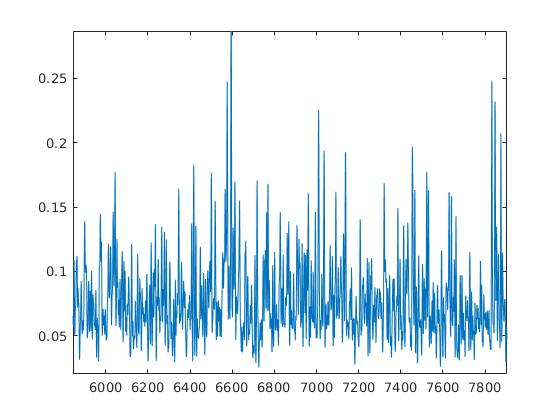

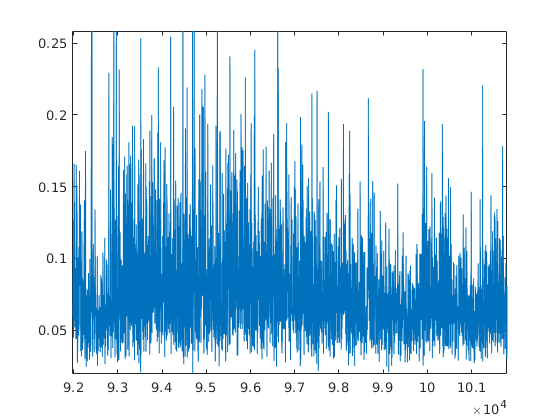

y =     0.0182
    0.0159
    0.0122
    0.0570
    0.0790
    0.0606
    0.0215
    0.0259
    0.0195
    0.0211


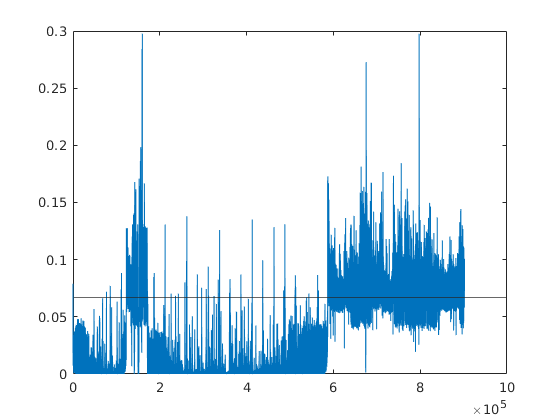

thr = 0.1200

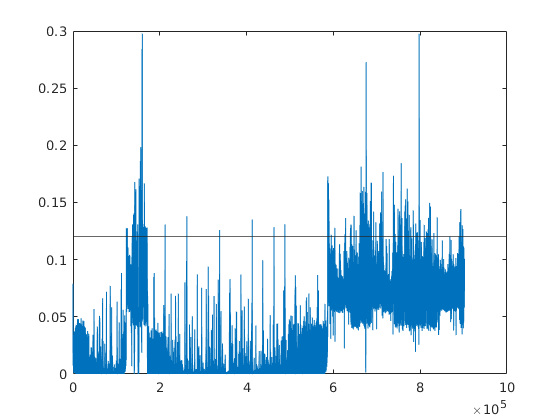

thr = 0.1200

times =       123007      123084      123703      124886      125291      125303      137018      138103      138143      138206      138371      138866      139283      139462      139653      140595      140685      140726      140942      142181      142192      142230      142280      142345      142376      142432      142473      142503      142552      142572      142603      142707      142744      142776      142851      142899      142913      142993      143148      143211      143265      143363      143404      143434      143726      143782      143842      144043      144151      144640


totalFiringUnits =        50370
       11468
       43702
       70149
        7916
        7122
       27338
        5223
        8724
       17189


unitFiringRate = 	1.0e+-7 *

    0.2477
    0.0564
    0.2149
    0.3450
    0.0389
    0.0350
    0.1345
    0.0257
    0.0429
    0.0845


times_prediction =       123007      123084      123703      124886      125291      125303      137018      138103      138143      138206      138371      138866      139283      139462      139653      140595      140685      140726      140942      142181      142192      142230      142280      142345      142376      142432      142473      142503      142552      142572      142603      142707      142744      142776      142851      142899      142913      142993      143148      143211      143265      143363      143404      143434      143726      143782      143842      144043      144151      144640


artifactStart = 75000

artifactEnd = 90000

all_times = 34×2 int64 matrix
    4780464    6505018
    6670018    8394572
    8559572   10272128
   10437128   12149685
   12314685   14033243
   14198243   15910800
   16075800   17800355
   17965355   19677955
   19842955   21567509
   21732509   23457064


all_times = 6×2 int64 matrix
   44335229   46059783
   48102340   49814940
   53753053   55465610
   55630610   57343166
   63146839   64871437
   65036437   66748994


aluminumTimes = 15×2 int64 matrix
   10437128   12149685
   12314685   14033243
   16075800   17800355
   19842955   21567509
   25499620   27218179
   31150290   32874844
   34917444   36630001
   36795001   38513559
   48102340   49814940
   49979940   51704494



aluminumEvents =

     []



tempEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


tempPredict =       138103
      138143
      138206
      138371
      138866
      139283
      139462
      139653
      140595
      140685


aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     12322958
    12345391
    12370223
    12397543
    12425986
    12432739
    12444079
    12456982
    12478976
    12561370


tempPredict =       163177
      163476
      163807
      164171
      164549
      164639
      164790
      164962
      165255
      166353


aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]



tempEvents =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]



tempEvents =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]



tempEvents =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]



tempEvents =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]



tempEvents =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]



tempEvents =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     48132800
    48137752
    48161165
    48195837
    48680479
    49029743
    49048724
    49049703
    49695916
    49705460


tempPredict =       640307
      640373
      640685
      641147
      647605
      652258
      652511
      652524
      661134
      661261


aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     49985748
    49990479
    50001052
    50001884
    50004512
    50005486
    50013064
    50020112
    50022138
    50023127


tempPredict =       664996
      665059
      665200
      665211
      665246
      665259
      665360
      665454
      665481
      665494


aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     55642238
    55655973
    55659057
    55665877
    55671357
    55674225
    55675111
    55679168
    55682240
    55694392


tempPredict =       740365
      740548
      740589
      740680
      740753
      740791
      740803
      740857
      740898
      741060


aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     57521160
    57527309
    57529634
    57537817
    57539090
    57542013
    57544276
    57559811
    57561160
    57564013


tempPredict =       765398
      765480
      765511
      765620
      765637
      765676
      765706
      765913
      765931
      765969


aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     59476847
    59654255
    59931247
    59932602
    59933651
    59935679
    59941009
    59944460
    59946111
    59951510


tempPredict =       791452
      793813
      797504
      797522
      797536
      797563
      797634
      797680
      797702
      797774


aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     61341506
    61342479
    61410927
    61490099
    61510513
    61536470
    61550137
    61604018
    61754335
    61797862


tempPredict =       816296
      816309
      817221
      818276
      818548
      818894
      819076
      819794
      821797
      822377


aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


tempEvents =     66936088
    66939022
    66953052
    67095486
    67099465
    67100209
    67115519
    67127827
    67133225
    67141493


tempPredict =       890829
      890868
      891055
      892953
      893006
      893016
      893220
      893384
      893456
      893566


aluminumEvents =     10440879
    10443886
    10448614
    10460997
    10498140
    10529425
    10542870
    10557199
    10627897
    10634655


experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB109_904'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: [1×1 struct]
            evokedEvents: [1×1 struct]


nonTimes = 11×2 int64 matrix
    6670018    8394572
    8559572   10272128
   17965355   19677955
   21732509   23457064
   23622064   25334620
   29272733   30985290
   33039844   34752444
   44335229   46059783
   46224783   47937340
   51869494   53588053



nonEvents =

     []




tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector




nonEvents =

  0×1 empty double column vector



tempInd =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848


tempPredict =       123007
      123084
      123703
      124886
      125291
      125303


nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848



tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848



tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848



tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848



tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848



tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848


tempInd =     44368430
    44369178
    44741183
    45367363


tempPredict =       590154
      590164
      595120
      603462


nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848
    44368430
    44369178
    44741183
    45367363


tempInd =     47123800
    47199832
    47212666
    47213331
    47222414
    47225491
    47227524
    47228420


tempPredict =       626865
      627878
      628049
      628058
      628179
      628220
      628246
      628258


nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848
    44368430
    44369178
    44741183
    45367363


tempInd =     52061216
    52062855
    52448226
    53103517
    53121986
    53123407
    53246940
    53250689
    53251962
    53270796


tempPredict =       692649
      692671
      697806
      706537
      706783
      706802
      708448
      708498
      708515
      708766


nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848
    44368430
    44369178
    44741183
    45367363


tempInd = 65244175

tempPredict = 868294

nonEvents =      9307456
     9313248
     9359698
     9448476
     9478944
     9479848
    44368430
    44369178
    44741183
    45367363


mutedTimes = 8×2 int64 matrix
    4780464    6505018
   14198243   15910800
   27383179   29107733
   38678559   40397117
   40562117   42280674
   42445674   44170229
   53753053   55465610
   63146839   64871437



mutedEvents =

     []




tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector




mutedEvents =

  0×1 empty double column vector




tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector




mutedEvents =

  0×1 empty double column vector




tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector




mutedEvents =

  0×1 empty double column vector




tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector




mutedEvents =

  0×1 empty double column vector




tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector




mutedEvents =

  0×1 empty double column vector



tempInd =     44103226
    44104497
    44107422
    44108998
    44110420
    44116133
    44117852
    44118783
    44119583
    44120404


tempPredict =       586620
      586637
      586676
      586697
      586716
      586792
      586815
      586827
      586838
      586849


mutedEvents =     44103226
    44104497
    44107422
    44108998
    44110420
    44116133
    44117852
    44118783
    44119583
    44120404


tempInd =     55458079
    55458903
    55461322


tempPredict =       737911
      737922
      737954


mutedEvents =     44103226
    44104497
    44107422
    44108998
    44110420
    44116133
    44117852
    44118783
    44119583
    44120404



tempInd =

  0×1 empty double column vector




tempPredict =

  0×1 empty double column vector



mutedEvents =     44103226
    44104497
    44107422
    44108998
    44110420
    44116133
    44117852
    44118783
    44119583
    44120404



rasters_aluminum =

  0×0 empty cell array




psth_aluminum =

     []



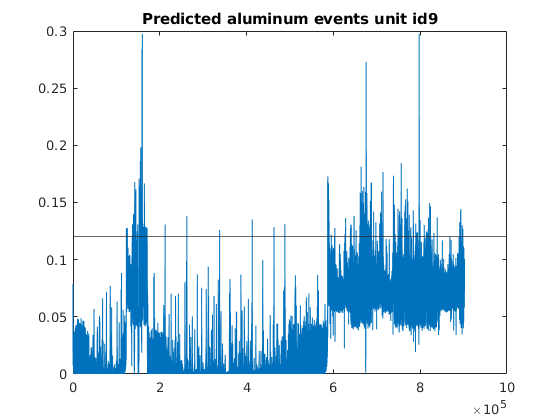


rasters_muted =

  0×0 empty cell array




psth_muted =

     []



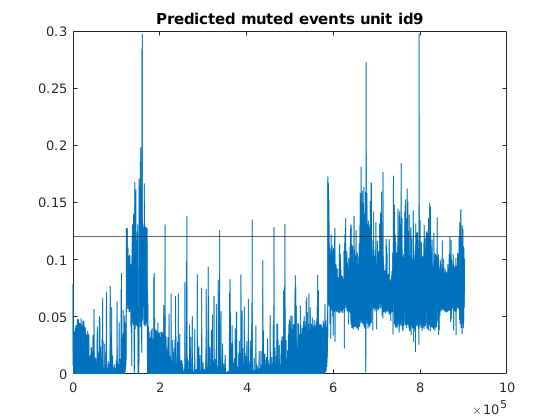


rasters_non =

  0×0 empty cell array




psth_non =

     []




rasters_aluminumMua =

  0×0 empty cell array




psth_aluminumMua =

     []



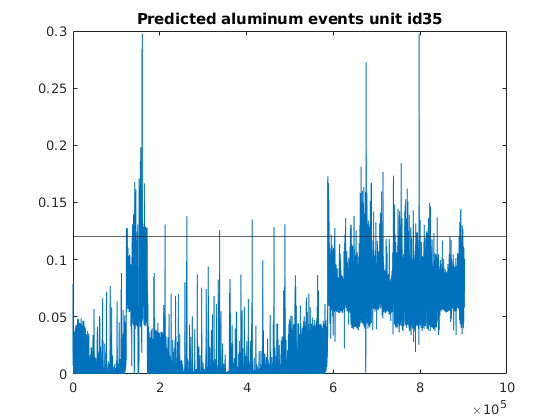


rasters_mutedMua =

  0×0 empty cell array




psth_mutedMua =

     []



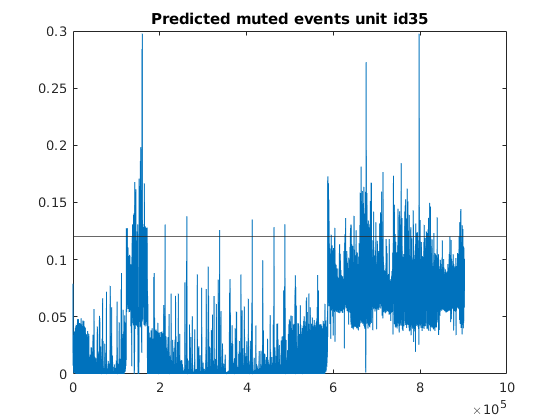


rasters_nonMua =

  0×0 empty cell array




psth_nonMua =

     []



psth_aluminumAll = 	1.0e+07 *

    1.0851    0.9713    1.0168    1.1306    1.1458    0.8498    1.0016    1.2520    1.0851    1.1685    1.1306    1.1230    1.1078    1.0927    1.1078    0.9257    0.8954    0.9637    1.0623    0.8954    0.9181    1.0775    1.0168    1.0927    1.0168    1.1078    0.8878    1.0851    1.0395    0.9864    0.8954    1.1230    1.0623    1.0092    1.1230    1.0016    0.8650    0.9713    1.0320    1.0775    0.9409    0.9940    1.0244    0.9940    1.0168    0.9409    1.1685    0.9485    1.1230    1.1230
    0.9665    0.8665    0.3666    0.6666    0.5999    0.6666    0.6666    0.7665    0.5999    0.4666    0.8332    0.5332    0.7999    0.8332    0.5999    0.6332    0.6999    0.8332    0.7665    0.6332    0.6332    0.4666    0.7665    0.6999    0.4333    0.5666    0.5666    0.5666    0.7665    0.6999    0.3999    0.7665    0.5666    0.7332    0.7332    0.5332    0.6666    0.7999    0.5332    0.5332    0.7332    0.6999    0.2999    0.3666    0.5666    0.4666    0.46

psth_mutedAll = 	1.0e+08 *

    0.1042    0.1042    0.0651    0.1042    0.1042    0.1563    0.1432    0.0781    0.0260    0.0651    0.1432    0.0781    0.1042    0.0781    0.0781    0.0781    0.1172    0.0781    0.0651    0.0781    0.1042    0.0651    0.0521    0.0651    0.1172    0.0781    0.0781    0.0781    0.0781    0.1432    0.1172    0.0651    0.0781    0.0912    0.0912    0.1693    0.0521    0.1042    0.1432    0.1302    0.0912    0.0651    0.1042    0.0912    0.1563    0.1302    0.1172    0.1302    0.1172    0.1172
    0.2860    0.2860    0.8579    0.2288    0.4004    0.5719    0.4004    0.5719    0.4576    0.4004    0.4004    0.4004    0.3432    0.6291    0.2860    0.5148    0.3432    0.4004    0.4576    0.2860    0.2288    0.5148    0.4576    0.2860    0.4004    0.2288    0.5719    0.1716    0.4576    0.4004    0.4004    0.1144    0.5148    0.1144    0.2860    0.4576    0.2860    0.2860    0.1144    0.3432    0.4004    0.2860    0.4004    0.1716    0.1716    0.2288    0.2288 

psth_nonAll = 	1.0e+07 *

    0.8971    0.5607    0.8971    1.0092    0.7849    1.1213    0.3364    1.1213    1.0092    1.2335    0.8971    1.1213    1.2335    0.8971    0.8971    1.1213    0.7849    1.1213    0.4485    0.4485    0.3364    0.4485    0.7849    0.2243    1.1213    0.8971    0.7849    1.1213    0.4485    0.5607    0.8971    0.6728    0.7849    0.5607    0.8971    0.6728    1.0092    0.6728    0.7849    0.8971    0.7849    0.3364    0.6728    1.1213    0.7849    0.6728    1.0092    0.8971    0.4485    1.3456
    0.4925    0.4925    0.9850    0.4925    0.9850    0.9850    0.9850    1.4775    0.4925    1.4775    0.4925    0.4925         0    0.4925    0.9850         0    0.9850    0.9850    1.9700         0    0.4925    0.4925    1.9700         0         0    0.4925    0.9850    0.4925    0.9850    0.9850    1.4775    0.4925    0.9850    0.9850         0    1.9700    0.4925         0    0.4925         0    1.4775    0.4925    0.9850         0         0    2.4626    0.4925   

mutSTD = 	1.0e+06 *

    1.4602    2.1249    3.2525    1.4102    2.5093    2.1409    1.6749    2.3117    2.1683    2.0153    2.0587    2.1700    1.5491    2.5688    1.8047    2.7043    1.8250    2.3903    1.8584    2.7859    2.1036    2.1522    1.9010    1.6192    2.2400    2.4069    2.9341    2.8857    1.8082    1.6119    2.0009    2.3551    1.9666    2.8919    2.8192    2.1494    2.2673    2.1569    1.3105    2.3378    1.7417    1.4128    2.7998    1.3102    1.4932    1.7201    2.1099    1.9640    2.5131    1.1005


alumSTD = 	1.0e+06 *

    0.9455    1.0897    1.0507    1.0065    0.9985    1.0704    0.9640    0.8451    0.8821    1.0082    0.9632    0.9733    1.0369    0.9769    1.0433    0.9033    0.9399    0.9187    1.2362    0.9308    0.9552    0.9839    1.0822    0.9848    1.0180    0.8044    0.8982    0.9038    0.9012    1.0082    0.9185    0.8315    0.9187    0.8602    0.9144    0.8925    1.0750    0.9867    0.9294    0.9674    0.8989    0.9981    0.9769    0.9228    0.8988    0.9971    1.0382    1.2019    1.0793    1.0078


nonSTD = 	1.0e+06 *

    1.7284    1.5916    1.6261    2.2146    1.6434    1.5994    1.8034    1.7836    1.3643    1.5208    1.2860    1.7091    1.5201    0.8107    1.4048    1.4796    1.0938    1.8436    1.3695    1.0084    1.0649    1.7965    1.6974    1.1703    1.6378    1.3701    1.2512    1.3650    1.4265    1.0033    1.3585    0.9345    1.0940    1.3967    1.5392    1.5550    1.0602    1.6052    1.1707    1.1761    1.2172    1.6695    1.2947    1.6412    1.5223    1.7327    2.3353    1.0144    1.4443    1.4181


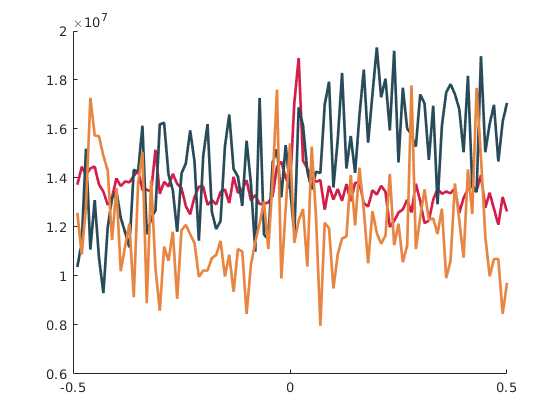

meanSound = struct with fields:
    aluminumMean: [532×400 double]
       mutedMean: [87×30000 double]
         nonMean: [325×30000 double]


meanSound = struct with fields:
    aluminumMean: [532×400 double]
       mutedMean: [31×400 double]
         nonMean: [325×30000 double]


meanSound = struct with fields:
    aluminumMean: [532×400 double]
       mutedMean: [31×400 double]
         nonMean: [36×400 double]


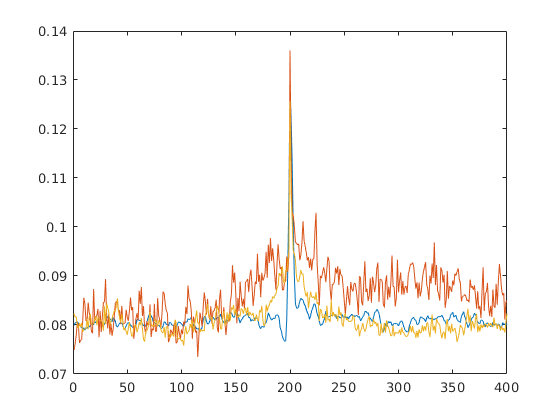

meanSound = struct with fields:
    aluminumMean: [532×30000 double]
       mutedMean: [31×30000 double]
         nonMean: [36×30000 double]